# Exam July 11, 2018

## Exercise 1

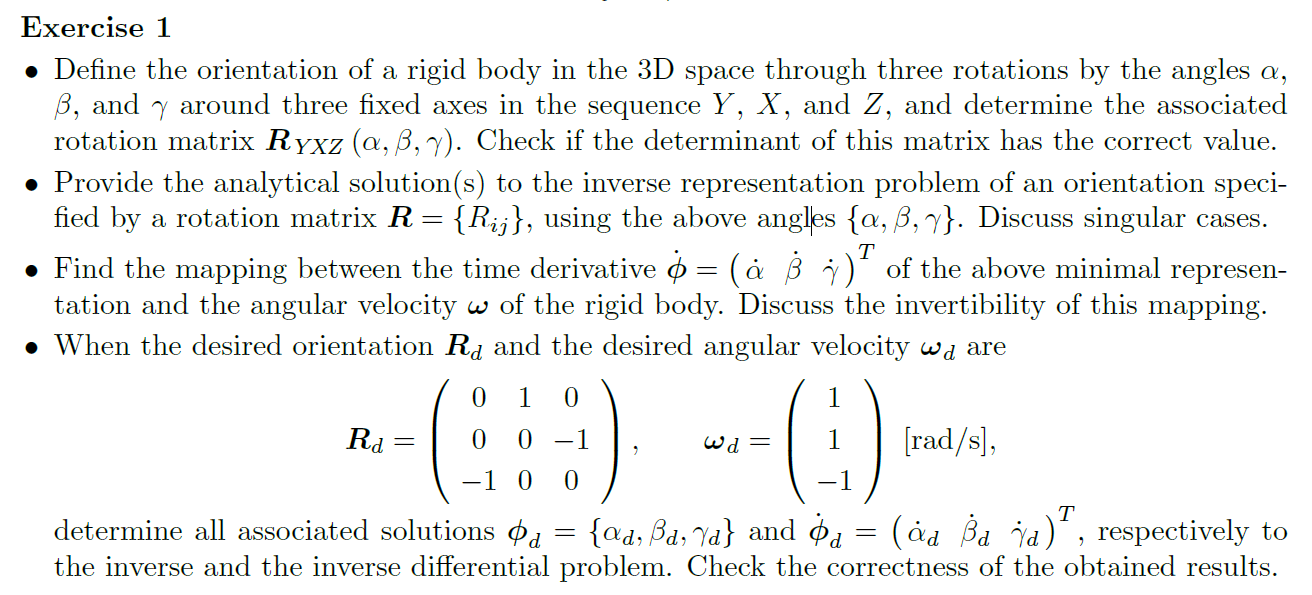

syms alpha beta gamma
angles = [alpha beta gamma]

$$angles = \left(\begin{array}{ccc} \alpha & \beta & \gamma \end{array}\right)$$

$$ans = 1$$


[Rx Ry Rz] = getEulerRotationMatrices()

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \right) & -\sin\left(\beta \right)\\ 0 & \sin\left(\beta \right) & \cos\left(\beta \right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} \cos\left(\alpha \right) & 0 & \sin\left(\alpha \right)\\ 0 & 1 & 0\\ -\sin\left(\alpha \right) & 0 & \cos\left(\alpha \right) \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & 0\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%To get the rotation matrix after the sequence of rotation YXZ, the product
%of matrices must be inverted
Ryxz = Rz*Rx*Ry

$$Ryxz = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & -\cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)+\cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)\\ \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\beta \right)\,\cos\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\gamma \right)-\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ -\cos\left(\beta \right)\,\sin\left(\alpha \right) & \sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$

%It can be probed that it is orthonormal with determinant =  1
determinant = simplify(det(Ryxz))

$$determinant = 1$$

Rd = [0 1 0 ; 0 0 -1;-1 0 0 ]

Rd =      0     1     0
     0     0    -1
    -1     0     0



[a1 b1 g1] = solve(Ryxz == Rd, angles);
phi = [a1 b1 g1]

$$phi = \left(\begin{array}{ccc} \frac{\pi }{2} & 0 & -\frac{\pi }{2}\\ -\frac{\pi }{2} & \pi & \frac{\pi }{2} \end{array}\right)$$

## Exercise 2

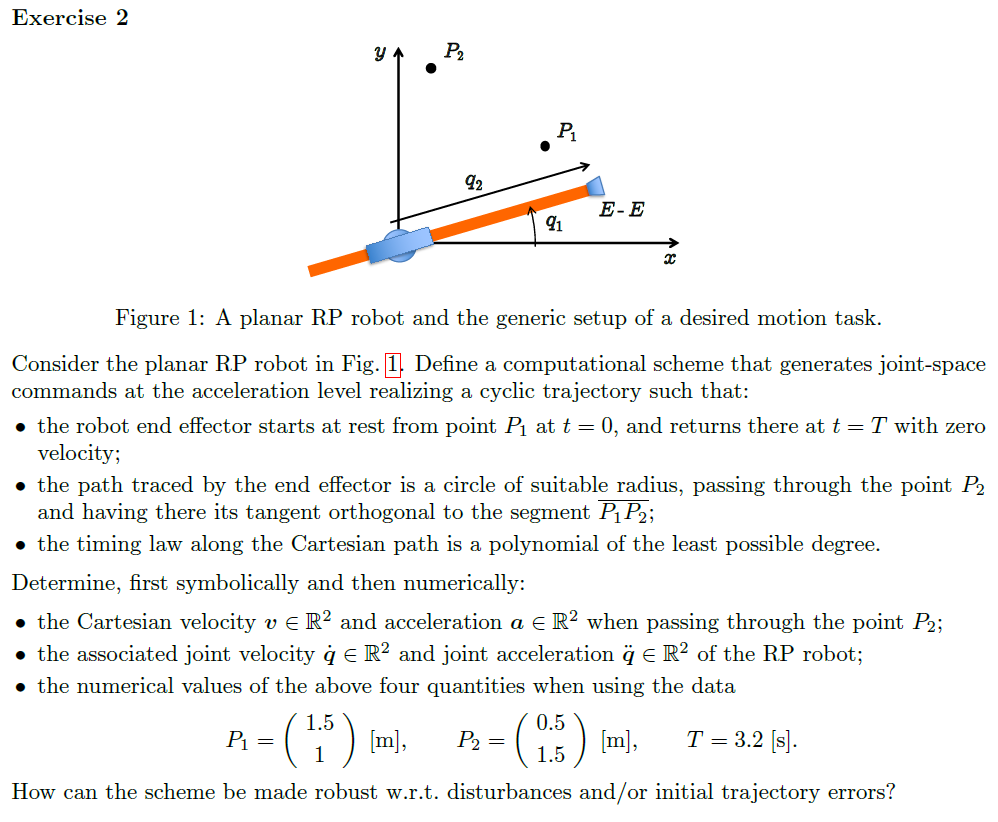

% Initialization of variables
clear
syms phi s t R x0 y0 T
p = sym('p',[2,1]);


% center point
p0 = (p(1)+p(2))/2

$$p0 = \frac{p_{1}}{2}+\frac{p_{2}}{2}$$


% Parametric circular path
p_s = [x0; y0] + R*[cos(s+phi);sin(s+phi)]

$$p\_s = \left(\begin{array}{c} x_{0}+R\,\cos\left(\phi +s\right)\\ y_{0}+R\,\sin\left(\phi +s\right) \end{array}\right)$$

pd_s = diff(p_s,s)

$$pd\_s = \left(\begin{array}{c} -R\,\sin\left(\phi +s\right)\\ R\,\cos\left(\phi +s\right) \end{array}\right)$$

pdd_s = diff(pd_s,s) 

$$pdd\_s = \left(\begin{array}{c} -R\,\cos\left(\phi +s\right)\\ -R\,\sin\left(\phi +s\right) \end{array}\right)$$


% Cubic polynomial in time
s_t = 2*pi*(3*(t/T)^2 - 2*(t/T)^3)

$$s\_t = 2\,\pi \,\left(\frac{3\,t^{2}}{T^{2}}-\frac{2\,t^{3}}{T^{3}}\right)$$

sd_t = diff(s_t,t)

$$sd\_t = 2\,\pi \,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)$$

sdd_t = diff(sd_t,t)

$$sdd\_t = -2\,\pi \,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$


% Test. This equals PI, so it means that at the middle of the period, the
% EE will be on the opposite side, which is right!.
%s_t(T/2)

v = pd_s*sd_t

$$v = \left(\begin{array}{c} -2\,\pi \,R\,\sin\left(\phi +s\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)\\ 2\,\pi \,R\,\cos\left(\phi +s\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right) \end{array}\right)$$

subs(v,[s,t],[pi,T/2])

$$ans = \left(\begin{array}{c} \frac{3\,\pi \,R\,\sin\left(\phi \right)}{T}\\ -\frac{3\,\pi \,R\,\cos\left(\phi \right)}{T} \end{array}\right)$$


a = pd_s*sdd_t + pdd_s*sd_t^2

$$a = \begin{array}{l} \left(\begin{array}{c} 2\,\pi \,R\,\sin\left(\phi +s\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)-4\,R\,\pi^{2}\,\cos\left(\phi +s\right)\,\sigma_{1}\\ -4\,R\,\pi^{2}\,\sin\left(\phi +s\right)\,\sigma_{1}-2\,\pi \,R\,\cos\left(\phi +s\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)}^{2} \end{array}$$

subs(a,[s,t],[pi,T/2])

$$ans = \left(\begin{array}{c} \frac{9\,R\,\pi^{2}\,\cos\left(\phi \right)}{T^{2}}\\ \frac{9\,R\,\pi^{2}\,\sin\left(\phi \right)}{T^{2}} \end{array}\right)$$

Joint space

n =2

n = 2

q = sym('q',[n,1])

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

qd = sym('qd',[n,1])

$$qd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2} \end{array}\right)$$

qdd = sym('qdd',[n,1])

$$qdd = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\\ {\mathrm{qdd}}_{2} \end{array}\right)$$

p = [qt(2)*cos(qt(1)) ; qt(2)*sin(qt(1))]

$$p = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\\ \sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) \end{array}\right)$$

var_ind = 't';
var_dep = 'q';
var_set =[]


var_set =

     []



syms(var_ind)
for i=1:n
   var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
   syms(var_dep_str);
   var_set = [var_set str2sym(var_dep_str)]; % appends the variable to the set
end
syms t
qt = var_set.'

$$qt = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

qdt = diff(qt,t)

$$qdt = \left(\begin{array}{c} \frac{\partial }{\partial t}q_{1}\left(t\right)\\ \frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

%pd = 
pd = diff(p)

$$pd = \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

pdd = diff(pd)

$$pdd = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\left(t\right)\right)\,\sigma_{2}-\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,2-\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{1}-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{3}\\ \sin\left(q_{1}\left(t\right)\right)\,\sigma_{2}+\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\,2-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{1}+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right)\,\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$


% Left incomplete. A lot of manual work. Easily made on paper.